clear
clc
close all

PID - perturbación

P = tf([0 0 0 1], [1 6 5 0])

P =
 
          1
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.



Kp = 39.42;
Ti = 3.077;
Td = 0.7692;
C = tf([Kp*Td Kp Kp/Ti], [0 1 0])

C =
 
  30.32 s^2 + 39.42 s + 12.81
  ---------------------------
               s
 
Continuous-time transfer function.



Hd = feedback(P,C)

Hd =
 
                      s
  -----------------------------------------
  s^4 + 6 s^3 + 35.32 s^2 + 39.42 s + 12.81
 
Continuous-time transfer function.



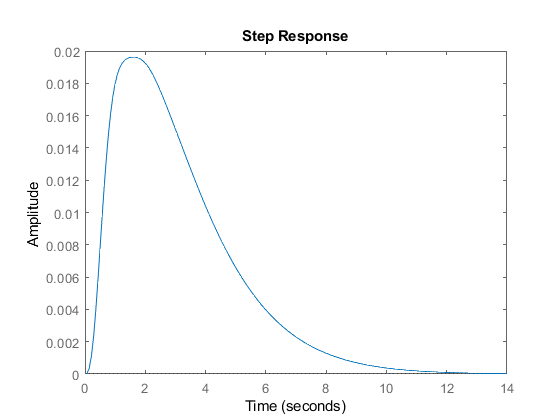

step(Hd);

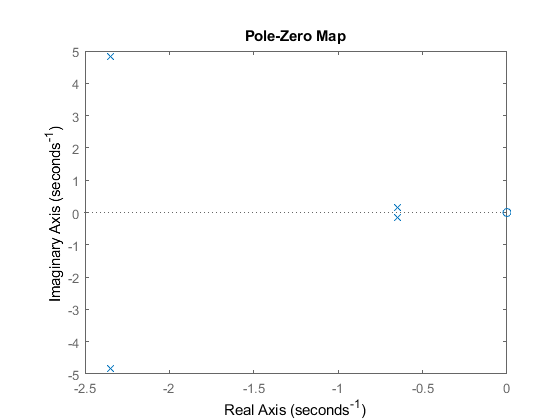

pzmap(Hd)

Controlador I-PD -  perturbación

Gd = tf([Td 1], 1)

Gd =
 
  0.7692 s + 1
 
Continuous-time transfer function.



Gp = tf(Kp,1)

Gp =
 
  39.42
 
Static gain.



Gi = tf([0 1], [Ti 0])

Gi =
 
     1
  -------
  3.077 s
 
Continuous-time transfer function.



HdIPD = feedback(P,Gp*(Gi+Gd))

HdIPD =
 
                        3.077 s
  ---------------------------------------------------
  3.077 s^4 + 18.46 s^3 + 108.7 s^2 + 121.3 s + 39.42
 
Continuous-time transfer function.



step(HdIPD)

pzmap(HdIPD)